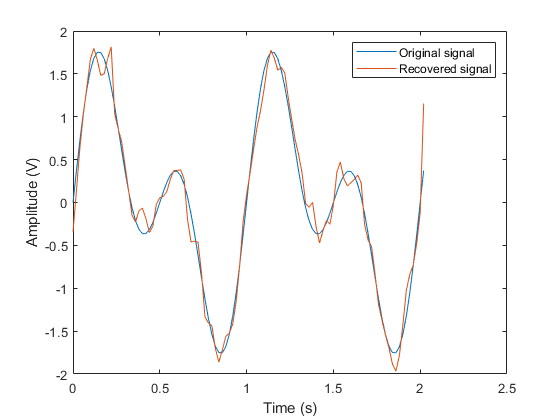

fs = 50; 
t = (0:2*fs+1)'/fs;
%Here we create a sinusoidal signal as an input signal
x = sin(2*pi*t) + sin(4*pi*t);
%Now we setting the carrier frequency and phase deviation.
fc = 10; 
phasedev = pi/2;
%Modulate the input signal.
tx = pmmod(x,fc,fs,phasedev);
%Pass the signal through an AWGN(Additive Gaussian White Noise) channel.
rx = awgn(tx,10,'measured');
%Demodulate the noisy signal.
y = pmdemod(rx,fc,fs,phasedev);
%Plot the original and recovered signals.
figure; plot(t,[x y]);
legend('Original signal','Recovered signal');
xlabel('Time (s)')
ylabel('Amplitude (V)')